% Comparative analysis on Synthetic Data
close all
clear

tic
addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))

make_db

workingOnServer = 0;

if workingOnServer
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    ANALYSIS_DIR = strcat(HOME_DIR, 'Work/Analysis');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    ANALYSIS_DIR = strcat(HOME_DIR2, 'Work/Analysis');
end

plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

figureDetails = compileFigureDetails(16, 2, 5, 0.5, 'inferno'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
%Extra colormap options: inferno/plasma/viridis/magma


%% Load Synthetic Data
if plotRefQ
    gDate = 20210618; %generation date
    gRun = 1; %generation run number
    nDatasets = 33;
    synthDataFilePath = sprintf('/Users/ananth/Desktop/Work/Analysis/Imaging/M26/20180514/synthDATA_%i_gRun%i_batch_%i.mat', gDate, gRun, nDatasets);
    load(synthDataFilePath)
end

%% Load Analysis Results
if plotAnalysedQs
    cDate = 20210618; %consolidation date
    cRun = 1; %consolidation run number
    analysisFilePath = sprintf('/Users/ananth/Desktop/Work/Analysis/Imaging/M26/20180514/M26_20180514_synthDataAnalysis_%i_cRun%i_cData.mat', cDate, cRun);
    load(analysisFilePath)
else
    cData = [];
end

%% For single session
dnum = 7;
fprintf('--> Dataset: %i\n', dnum)

--> Dataset: 7


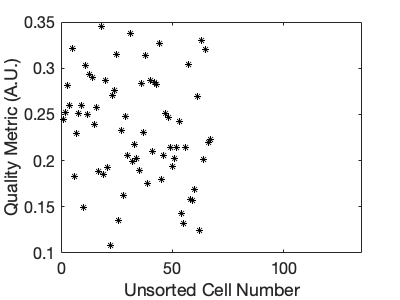

dfbf_2D = sdo_batch(dnum).syntheticDATA_2D;

normalizeScatterPlots = 0;  %for scatter plots
normalizeDataVisual = 1; % 0: global normalization; 1: cell-wise normalization

if normalizeDataVisual
    norm_dfbf_2D = zeros(size(dfbf_2D));
    for cell = 1:size(dfbf_2D)
        cellMax = max(squeeze(dfbf_2D(cell, :)));
        norm_dfbf_2D(cell, :) = dfbf_2D(cell, :)/cellMax;
    end
end

nCells = 135;
nFrames = 246;
nTrials = 5;
nMethods = 8;

fig1 = figure(1);
clf
set(fig1,'Position',[0, 200, 400, 300])
plot(sdo_batch(dnum).Q, 'k*')
xlim([0 nCells])
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Quality Metric (A.U.)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-1' ...
    '_BoS_synthData' ...
    '_Q_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

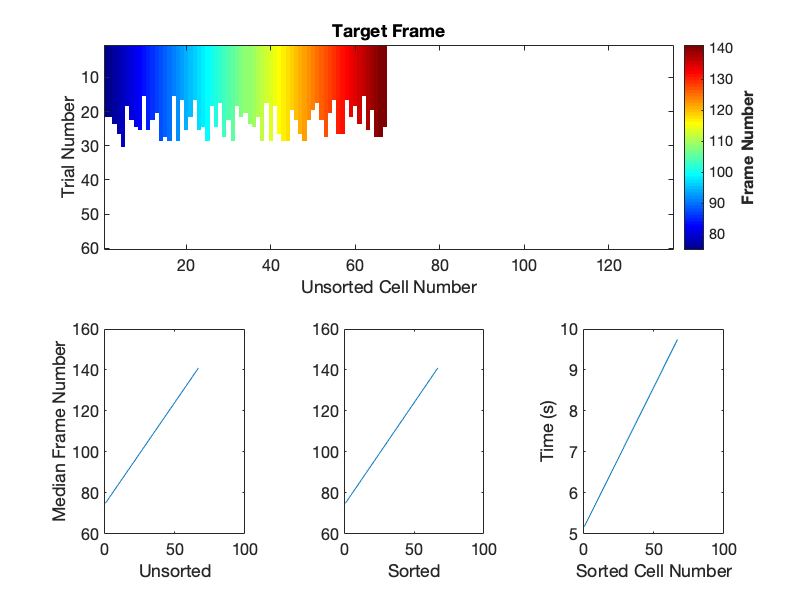


timeMatrix = sdo_batch(dnum).frameIndex;
fig2 = figure(2);
clf
set(fig2,'Position',[0, 200, 800, 600])
subplot(2, 8, 1:8)
%imagesc(timeMatrix(sdo_batch(dnum).ptcList, :)')
X = imagesc(timeMatrix');
set(X,'AlphaData',~isnan(timeMatrix'))
z = colorbar;
ylabel(z,'Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('jet')
%caxis([sdcp(dnum).startFrame sdcp(dnum).endFrame])
title('Target Frame', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 8, 9:10)
%plot(mean(timeMatrix(sdo_batch(dnum).ptcList, :), 2))
plot(nanmean(timeMatrix, 2))
%xlim([0 length(sdo_batch(dnum).ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Unsorted', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Median Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 8, 12:13)
%plot(sort(nanmean(timeMatrix(sdo_batch(dnum).ptcList, :), 2)))
plot(sort(nanmean(timeMatrix, 2)))
%xlim([0 length(sdo_batch(dnum).ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
%set(gca,'YTickLabel',[]);
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Sorted', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Median Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 8, 15:16)
%plot(sort(mean(timeMatrix(sdo_batch(dnum).ptcList, :), 2) / db.samplingRate))
plot(sort(nanmean(timeMatrix, 2) / db.samplingRate))
%xlim([0 length(sdo_batch(dnum).ptcList)])
%xlim([0 size(timeMatrix, 1)])
%ylim([0 db.nFrames])
% title('Target Frame', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Sorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-2' ...
    '_BoS_synthData' ...
    '_frameIndex_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

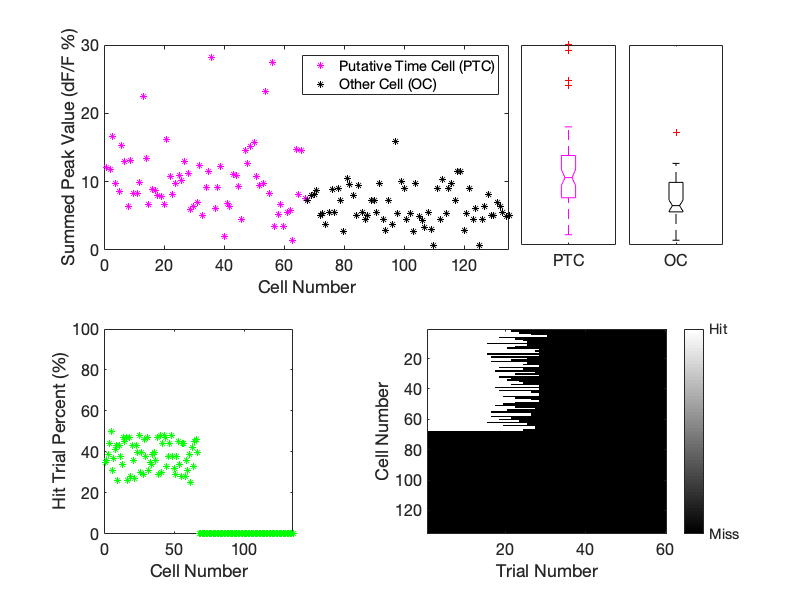

sdtc_peaks = nan(nCells, nTrials); % Putative Time Cells
sdoc_peaks = nan(nCells, nTrials); % Other Cells
for cell = 1:nCells
    for trial = 1:nTrials
        if ismember(cell, sdo_batch(dnum).ptcList)
            sdtc_peaks(cell, trial) = max(sdo_batch(dnum).syntheticDATA(cell, trial, :));
        else
            sdoc_peaks(cell, trial) = max(sdo_batch(dnum).syntheticDATA(cell, trial, :));
        end
    end
end
X1 = sum(sdtc_peaks, 2);
X2 = sum(sdoc_peaks, 2);

fig3 = figure(3);
clf
set(fig3,'Position',[0, 200, 800, 600])
subplot(2, 6, 1:4)
plot(X1, 'm*')
hold on
plot(X2, 'k*')
hold off
if length(X1) > length(X2)
    xlim([0 length(X1)])
else
    xlim([0 length(X2)])
end
% title('Putative Time Cells vs Other Cells', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Summed Peak Value (dF/F %)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
legend('Putative Time Cell (PTC)', 'Other Cell (OC)')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 6, 5)
boxplot(X1, ...
    'Notch','on', ...
    'Labels',{'PTC'}, ...
    'Whisker', 1, ...
    'Color', 'm')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 6, 6)
boxplot(X2, ...
    'Notch','on', ...
    'Labels',{'OC'}, ...
    'Whisker', 1, ...
    'Color', 'k')
ylim([0 max(X1)])
set(gca,'YTick',0:100:max(X1))
set(gca,'YTickLabel',[])
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 6, 7:8)
plot(sdo_batch(dnum).hitTrialPercent, 'g*')
xlim([0 nCells])
ylim([0 100])
xlabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Hit Trial Percent (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 6, 10:12)
imagesc(sdo_batch(dnum).hitTrials)
z = colorbar;
z.Ticks = [0, 1];
z.TickLabels = {'Miss', 'Hit'};
colormap('gray')
xlabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-3' ...
    '_BoS_synthData' ...
    '_trialSummedPeaks_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

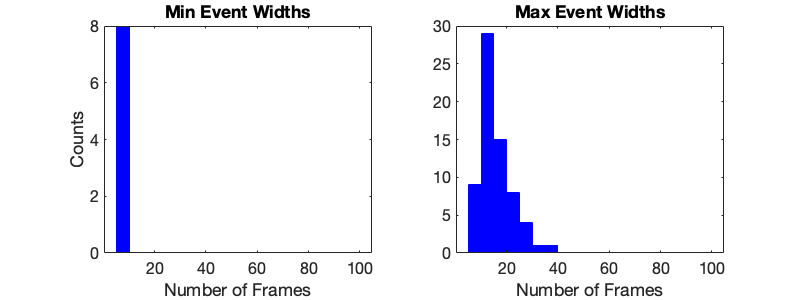


sdo_batch(dnum).actualEventWidth(sdo_batch(dnum).actualEventWidth == 0) = nan; % Ignore cases without an event
fig4 = figure(4);
clf
set(fig4,'Position',[0, 200, 800, 300])
edges = 5:5:100;
subplot(1,2,1)
histogram(sdo_batch(dnum).actualEventWidth(:,1), edges, ...
    'FaceColor', 'b', ...
    'EdgeColor', 'b', ...
    'FaceAlpha', 1);
title('Min Event Widths', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(1,2,2)
histogram(sdo_batch(dnum).actualEventWidth(:,2), edges, ...
    'FaceColor', 'b', ...
    'EdgeColor', 'b', ...
    'FaceAlpha', 1);
title('Max Event Widths', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Counts', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-4' ...
    '_BoS_synthData' ...
    '_ActualEventWidthRange_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

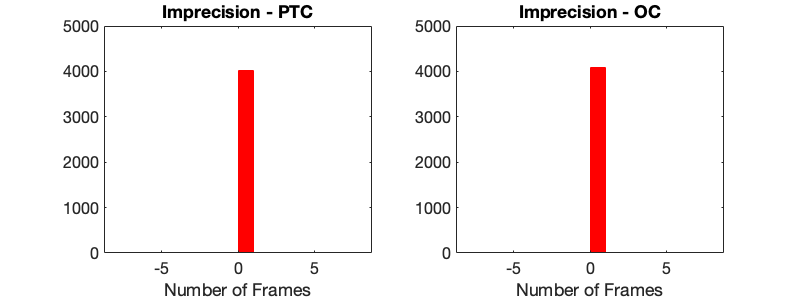


pad_ptc = sdo_batch(dnum).pad(sdo_batch(dnum).ptcList,:); % Putative Time Cells
pad_oc = sdo_batch(dnum).pad(sdo_batch(dnum).ocList,:); % Other Cells
fig5 = figure(5);
clf
set(fig5,'Position',[0, 200, 800, 300])
edges = -8:1:8;
subplot(1, 2, 1)
histogram(pad_ptc, edges, ...
    'FaceColor', 'r', ...
    'EdgeColor', 'r', ...
    'FaceAlpha', 1); % Min) %implicitly, binsize = 1 frame for low imprecisionFWHM
if sdcp(dnum).imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp(dnum).imprecisionFWHM/2)) floor(sdcp(dnum).imprecisionFWHM/2)])
end
title('Imprecision - PTC', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Counts', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(1, 2, 2)
histogram(pad_oc, edges, ...
    'FaceColor', 'r', ...
    'EdgeColor', 'r', ...
    'FaceAlpha', 1); % Min) %implicitly, binsize = 1 frame for low imprecisionFWHM
if sdcp(dnum).imprecisionFWHM ~= 0
    xlim([-1*(ceil(sdcp(dnum).imprecisionFWHM/2)) floor(sdcp(dnum).imprecisionFWHM/2)])
end
title('Imprecision - OC', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Number of Frames', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Counts', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-5' ...
    '_BoS_synthData' ...
    '_Imprecision_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

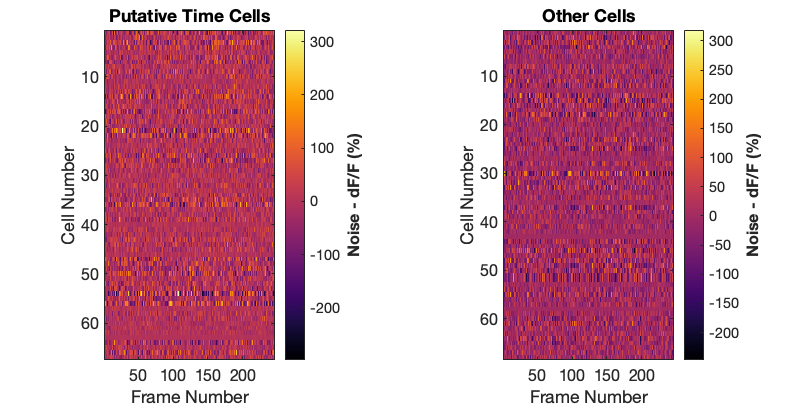


fig6 = figure(6);
set(fig6, 'Position', [300, 300, 800, 405])
clf
subplot(1, 8, 1:3)
imagesc(sdo_batch(dnum).noiseComponent(sdo_batch(dnum).ptcList, :).*100)
%colormap(figureDetails.colorMap)
colormap('inferno')
z = colorbar;
ylabel(z,'Noise - dF/F (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(1, 8, 6:8)
imagesc(sdo_batch(dnum).noiseComponent(sdo_batch(dnum).ocList, :) .*100)
%colormap(figureDetails.colorMap)
colormap('inferno')
z = colorbar;
ylabel(z,'Noise - dF/F (%)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-6' ...
    '_BoS_synthData' ...
    '_noiseComponent_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')


delta = 3;
skipFrames = [];
[ETH, ETH_3D, nbins] = getETH(sdo_batch(dnum).syntheticDATA, delta, skipFrames);

Now, developing ETH for 135 cells ...
... 50 cells analysed ...
... 100 cells analysed ...
... done!


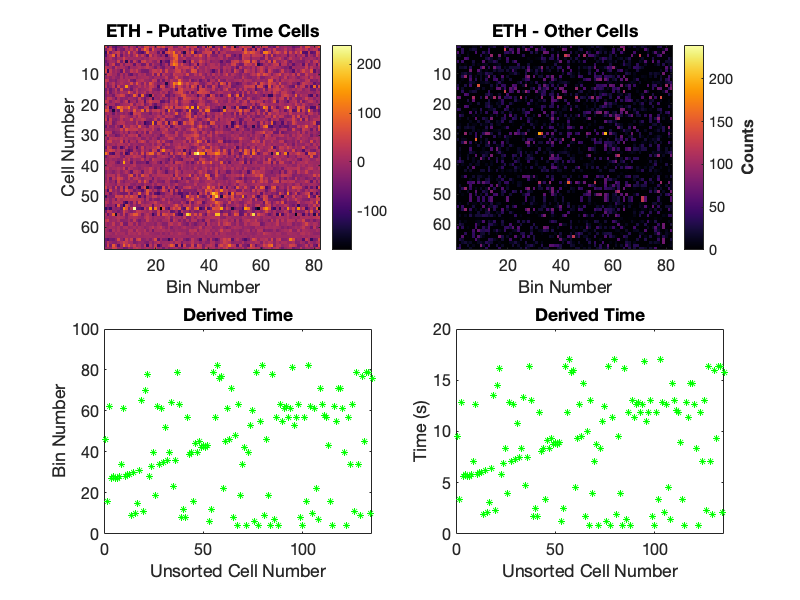

[~, derivedT] = max(ETH(:,:), [], 2); % Actual Time Vector
sdo_batch(dnum).T = derivedT;
fig7 = figure(7);
clf
set(fig7, 'Position', [300, 300, 800, 600])
subplot(2, 2, 1)
imagesc(ETH(sdo_batch(dnum).ptcList,:)); % Putative Time Cells
z = colorbar;
%set(z,'YTickLabel',({}))
colormap('inferno')
%caxis([0 max(max(ETH(sdo_batch(set).ptcList,:)))])
title('ETH - Putative Time Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 2, 2)
imagesc(ETH(sdo_batch(dnum).ocList,:)); % Other Cells
z = colorbar;
caxis([0 max(max(ETH(sdo_batch(dnum).ptcList,:)))]) % NOTE: setting limits based on the same expected for putative time cells.
ylabel(z,'Counts', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
colormap('inferno')
title('ETH - Other Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Cell Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 2, 3)
plot(derivedT, 'g*')
%xlim([0 length(sdo_batch(dnum).ptcList)])
xlim([0 nCells])
%ylim([0 nbins])
title('Derived Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Bin Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 2, 4)
plot((derivedT * delta )/ db.samplingRate, 'g*')
%xlim([0 length(sdo_batch(dnum).ptcList)])
xlim([0 nCells])
%ylim([0 nbins])
title('Derived Time', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-7' ...
    '_BoS_synthData' ...
    '_ETH_' ...
    db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session), ...
    '_' sdo_batch(dnum).endTime], ...
    '-djpeg')

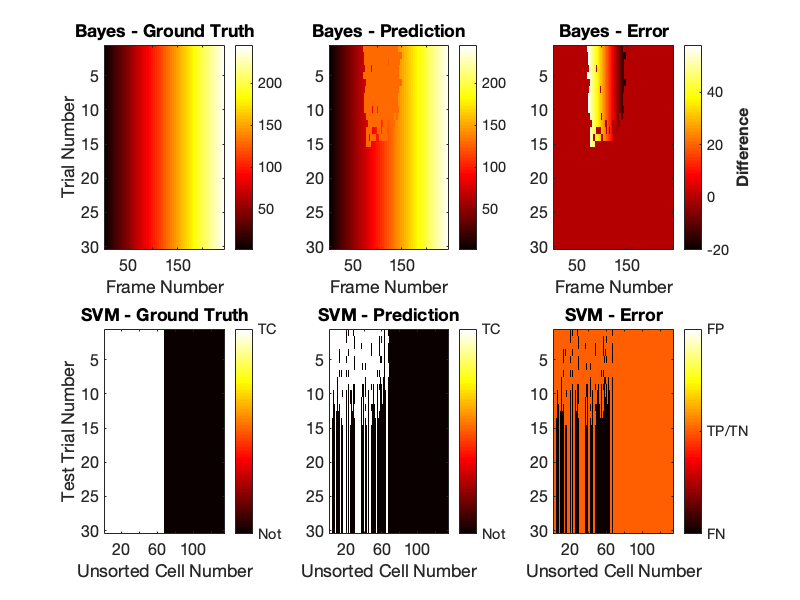


% Other predictions
fig8 = figure(8);
clf
set(fig8,'Position',[0, 200, 800, 600])
subplot(2, 3, 1)
imagesc(cData.methodB.mBOutput_batch(dnum).Yfit_actual_2D)
colormap('jet')
z = colorbar;
% ylabel(z,'Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title('Bayes - Ground Truth', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 3, 2)
imagesc(cData.methodB.mBOutput_batch(dnum).Yfit_2D)
colormap('hot')
z = colorbar;
% ylabel(z,'Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
title('Bayes - Prediction', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Trial Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 3, 3)
imagesc(cData.methodB.mBOutput_batch(dnum).YfitDiff_2D)
colormap('hot')
z = colorbar;
ylabel(z,'Difference', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
title('Bayes - Error', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Trial Frame Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 3, 4)
imagesc(cData.methodE.mEOutput_batch(dnum).Yfit_actual_2D)
colormap('hot')
z = colorbar('XTickLabel',{'Not', 'TC'}, ...
    'XTick', 0:1:1);
% ylabel(z,'Is Time Cell?', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
caxis([0 1])
title('SVM - Ground Truth', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Test Trial Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 3, 5)
imagesc(cData.methodE.mEOutput_batch(dnum).Yfit_2D)
colormap('hot')
z = colorbar('XTickLabel',{'Not', 'TC'}, ...
    'XTick', 0:1:1);
% ylabel(z,'Is Time Cell?', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
caxis([0 1])
title('SVM - Prediction', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Test Trial Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(2, 3, 6)
imagesc(cData.methodE.mEOutput_batch(dnum).YfitDiff_2D)
colormap('hot')
z = colorbar('XTickLabel',{'FN', 'TP/TN', 'FP'}, ...
    'XTick', -1:1:1);
% ylabel(z,'Type', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
caxis([-1 1])
title('SVM - Error', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% ylabel('Test Trial Number', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-8' ...
    '_BoS_synthData' ...
    '_predictions_' ...
    db.mouseName '_' num2str(db.date)], ...
    '-djpeg')

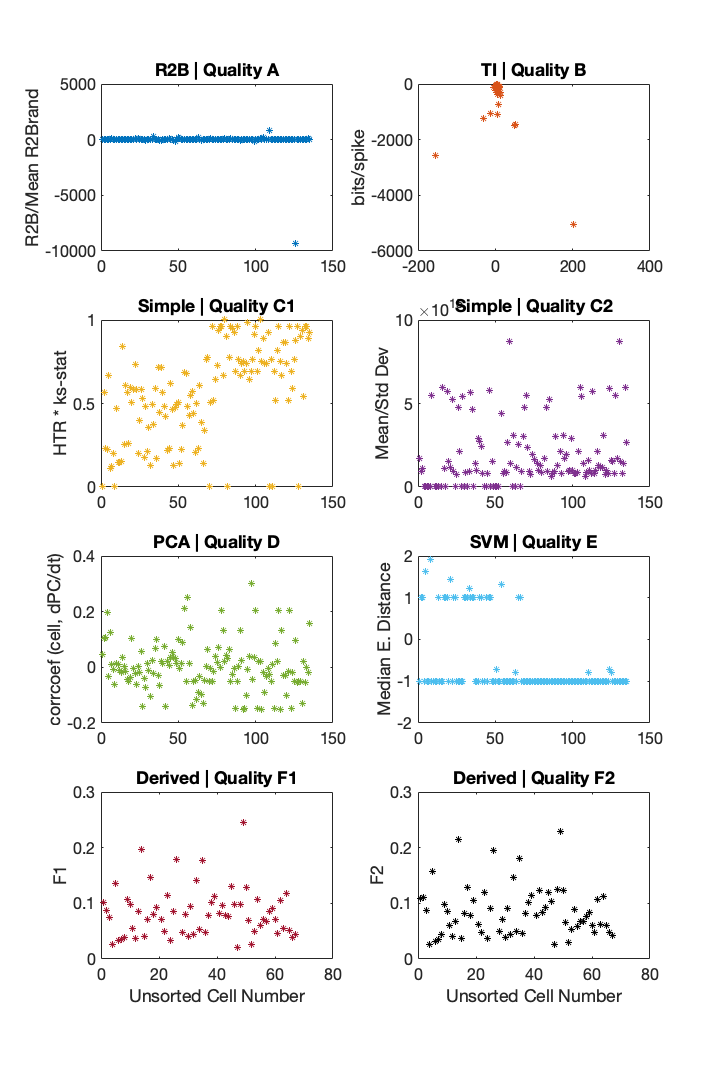


% Q scores for all methods - independently
c1 = [0, 0.4470, 0.7410]; %blue
c2 = [0.8500, 0.3250, 0.0980]; %red
c3 = [0.9290, 0.6940, 0.1250]; %yellow
c4 = [0.4940, 0.1840, 0.5560]; %purple
c5 = [0.4660, 0.6740, 0.1880]; %green
c6 = [0.3010, 0.7450, 0.9330]; %cyan
c7 = [0.6350, 0.0780, 0.1840]; %brown
c8 = [0, 0, 0]; %black
fig9 = figure(9);
set(fig9,'Position',[300, 300, 800, 1200])
clf
subplot(4, 2, 1)
plot(cData.methodA.mAOutput_batch(dnum).Q, '*', 'Color', c1)
title('R2B | Quality A', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Unsorted Cell Number', ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
ylabel('R2B/Mean R2Brand', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 2)
plot(cData.methodB.mBOutput_batch(dnum).Q, '*', 'Color', c2)
title('TI | Quality B', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Unsorted Cell Number', ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
ylabel('bits/spike', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 3)
plot(cData.methodC.mCOutput_batch(dnum).Q1, '*', 'Color', c3)
title('Simple | Quality C1', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Unsorted Cell Number', ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
ylabel('HTR * ks-stat', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 4)
plot(cData.methodC.mCOutput_batch(dnum).Q2, '*', 'Color', c4)
title('Simple | Quality C2', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Unsorted Cell Number', ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
ylabel('Mean/Std Dev', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 5)
plot(cData.methodD.mDOutput_batch(dnum).Q, '*', 'Color', c5)
title('PCA | Quality D', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
% xlabel('Unsorted Cell Number', ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
ylabel('corrcoef (cell, dPC/dt)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 6)
% imagesc(cData.methodE.mEOutput_batch(dnum).Q_2D)
% colormap('inferno')
% z = colorbar;
% ylabel(z,'Classification Score', ...
%     'FontSize', figureDetails.fontSize, ...
%     'FontWeight', 'bold')
% caxis([min(min(cData.methodE.mEOutput_batch(dnum).Q_2D)), max(max(cData.methodE.mEOutput_batch(dnum).Q_2D))])
plot(cData.methodE.mEOutput_batch(dnum).Q, '*', 'Color', c6)
title('SVM | Quality E', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
%     xlabel('Unsorted Cell Number', ...
%         'FontSize', figureDetails.fontSize,...
%         'FontWeight', 'bold')
ylabel('Median E. Distance', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 7)
plot(cData.methodF.mFOutput_batch(dnum).Q1, '*', 'Color', c7)
title('Derived | Quality F1', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('F1', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)

subplot(4, 2, 8)
plot(cData.methodF.mFOutput_batch(dnum).Q2, '*', 'Color', c8)
title('Derived | Quality F2', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('F2', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize)
print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-9' ...
    '_BoS_synthData' ...
    '_allScores_' ...
    db.mouseName '_' num2str(db.date)], ...
    '-djpeg')


fig10 = figure(10);
clf
set(fig10,'Position',[0, 200, 800, 800])
subplot(12, 9, 1:27) %Data visual
if normalizeDataVisual
    imagesc(norm_dfbf_2D(:, 1:nTrials*nFrames)*100);
    minVal = min(min(norm_dfbf_2D))*100;
    maxVal = max(max(norm_dfbf_2D))*100;
else
    imagesc(dfbf_2D(:, 1:nTrials*nFrames)*100);
    minVal = min(min(dfbf_2D))*100;
    maxVal = max(max(dfbf_2D))*100;
end
caxis([minVal maxVal]);
%colormap(figureDetails.colorMap)
colormap('inferno')
% title(sprintf('%i - First 5 Trials', db.date), ...
%     'FontSize', figureDetails.fontSize,...
%     'FontWeight', 'bold')
title(sprintf('Synthetic Dataset %i - First 5 Trials', dnum), ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Frame Numbers', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('All Cells', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
z = colorbar;
if normalizeDataVisual
    ylabel(z,'Cell Norm. dF/F (%)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
else
    ylabel(z,'dF/F (%)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
end
set(gca,'FontSize', figureDetails.fontSize)

%Scatter plots
%C = distinguishable_colors(6);
if normalizeScatterPlots == 1
    for count = 1:nMethods
        x = sdo_batch(dnum).Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = cData.methodA.mAOutput_batch(dnum).normQ;
            scatter(x, y, ...
                'MarkerEdgeColor', c1, ...
                'MarkerFaceColor', c1, ...
                'LineWidth',1.5)
            ylabel('A', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = cData.methodB.mBOutput_batch(dnum).normQ;
            scatter(x, y, ...
                'MarkerEdgeColor', c2, ...
                'MarkerFaceColor', c2, ...
                'LineWidth',1.5)
            ylabel('B', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = cData.methodC.mCOutput_batch(dnum).normQ1;
            scatter(x, y, ...
                'MarkerEdgeColor', c3, ...
                'MarkerFaceColor', c3, ...
                'LineWidth',1.5)
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = cData.methodC.mCOutput_batch(dnum).normQ2;
            scatter(x, y, ...
                'MarkerEdgeColor', c4, ...
                'MarkerFaceColor', c4, ...
                'LineWidth',1.5)
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = cData.methodD.mDOutput_batch(dnum).normQ;
            scatter(x, y, ...
                'MarkerEdgeColor', c5, ...
                'MarkerFaceColor', c5, ...
                'LineWidth',1.5)
            ylabel('D', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = cData.methodE.mEOutput_batch(dnum).normQ;
            scatter(x, y, ...
                'MarkerEdgeColor', c6, ...
                'MarkerFaceColor', c6, ...
                'LineWidth',1.5)
            ylabel('E', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = cData.methodF.mFOutput_batch(dnum).normQ1;
            scatter(x, y, ...
                'MarkerEdgeColor', c7, ...
                'MarkerFaceColor', c7, ...
                'LineWidth',1.5)
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = cData.methodF.mFOutput_batch(dnum).normQ2;
            scatter(x, y, ...
                'MarkerEdgeColor', c8, ...
                'MarkerFaceColor', c8, ...
                'LineWidth',1.5)
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        else
            str = {'Will add dataset','details here'};
            text(2,7,str)
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
else %No normalization
    for count = 1:nMethods
        x = sdo_batch(dnum).Q;
        if count == 1
            subplot(12, 9, [37:38, 46:47])
            y = cData.methodA.mAOutput_batch(dnum).Q;
            scatter(x, y, ...
                'MarkerEdgeColor', c1, ...
                'MarkerFaceColor', c1, ...
                'LineWidth',1.5)
            ylabel('A', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 2
            subplot(12, 9, [40:41, 49:50])
            y = cData.methodB.mBOutput_batch(dnum).Q;
            scatter(x, y, ...
                'MarkerEdgeColor', c2, ...
                'MarkerFaceColor', c2, ...
                'LineWidth',1.5)
            ylabel('B', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 3
            subplot(12, 9, [43:44, 52:53])
            y = cData.methodC.mCOutput_batch(dnum).Q1;
            scatter(x, y, ...
                'MarkerEdgeColor', c3, ...
                'MarkerFaceColor', c3, ...
                'LineWidth',1.5)
            ylabel('C1', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 4
            subplot(12, 9, [64:65, 73:74])
            y = cData.methodC.mCOutput_batch(dnum).Q2;
            scatter(x, y, ...
                'MarkerEdgeColor', c4, ...
                'MarkerFaceColor', c4, ...
                'LineWidth',1.5)
            ylabel('C2', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 5
            subplot(12, 9, [67:68, 76:77])
            y = cData.methodD.mDOutput_batch(dnum).Q;
            scatter(x, y, ...
                'MarkerEdgeColor', c5, ...
                'MarkerFaceColor', c5, ...
                'LineWidth',1.5)
            ylabel('D', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 6
            subplot(12, 9, [70:71, 79:80])
            y = cData.methodE.mEOutput_batch(dnum).Q;
            scatter(x, y, ...
                'MarkerEdgeColor', c6, ...
                'MarkerFaceColor', c6, ...
                'LineWidth',1.5)
            ylabel('E', ...
                'FontSize', figureDetails.fontSize)
        elseif count == 7
            subplot(12, 9, [91:92, 100:101])
            y = cData.methodF.mFOutput_batch(dnum).Q1;
            scatter(x, y, ...
                'MarkerEdgeColor', c7, ...
                'MarkerFaceColor', c7, ...
                'LineWidth',1.5)
            ylabel('F1', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        elseif count == 8
            subplot(12, 9, [94:95, 103:104])
            y = cData.methodF.mFOutput_batch(dnum).Q2;
            scatter(x, y, ...
                'MarkerEdgeColor', c8, ...
                'MarkerFaceColor', c8, ...
                'LineWidth',1.5)
            ylabel('F2', ...
                'FontSize', figureDetails.fontSize, ...
                'FontWeight', 'bold')
        else
        end
        xlabel('Ref Q', ...
            'FontSize', figureDetails.fontSize, ...
            'FontWeight', 'bold')
        xlim([0, 1])
        set(gca,'FontSize', figureDetails.fontSize)
    end
end

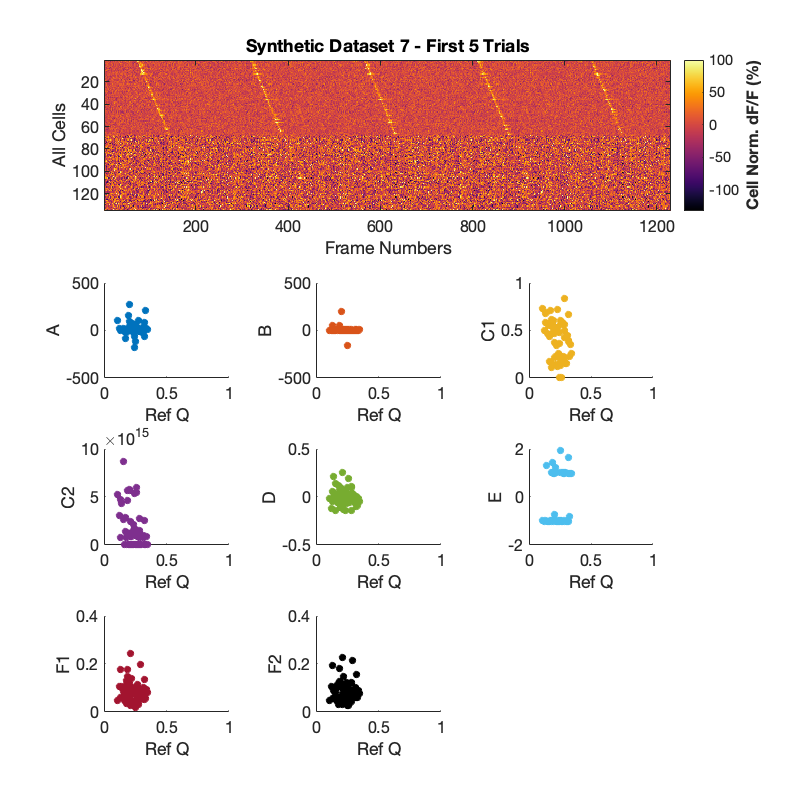

clear x
clear y
print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-10' ...
    '_BoS_synthData' ...
    '_dataVisualnScatter' ...
    db.mouseName '_' num2str(db.date)], ...
    '-djpeg')

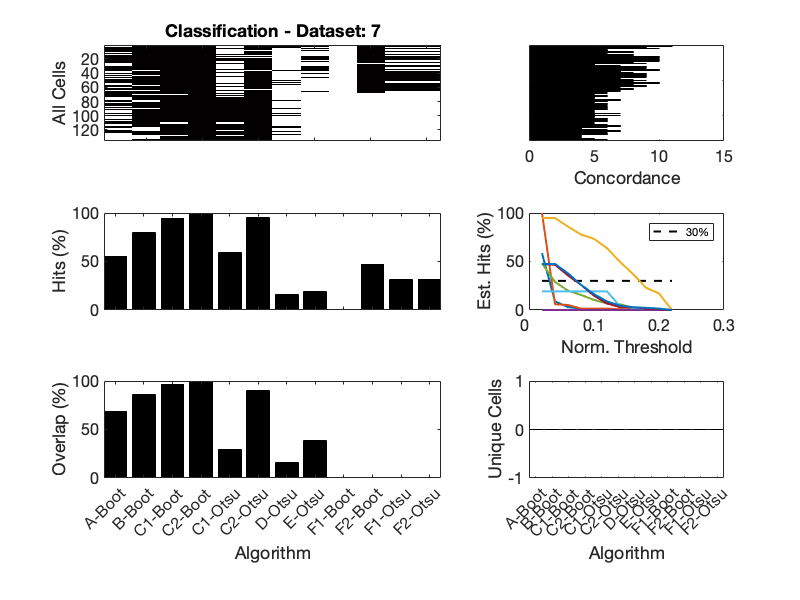

    
    % Classification
    nAlgos = 12;
    iddTimeCells = zeros(nCells, nAlgos);
    allScores = zeros(nCells, nMethods);
    
    %(fontSize, lineWidth, markerSize, transparency, colorMap)
    figureDetails = compileFigureDetails(16, 2, 5, 0, 'hot'); %inferno/plasma/viridis/magma
    
    for algo = 1:nAlgos
        if algo == 1
            iddTimeCells(:, algo) = squeeze(cData.methodA.mAOutput_batch(dnum).timeCells);
        elseif algo == 2
            iddTimeCells(:, algo) = squeeze(cData.methodB.mBOutput_batch(dnum).timeCells);
        elseif algo == 3
            iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells1);
        elseif algo == 4
            iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells2);
        elseif algo == 5
            iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells3);
        elseif algo == 6
            iddTimeCells(:, algo) = squeeze(cData.methodC.mCOutput_batch(dnum).timeCells4);
        elseif algo == 7
            iddTimeCells(:, algo) = squeeze(cData.methodD.mDOutput_batch(dnum).timeCells);
        elseif algo == 8
            iddTimeCells(:, algo) = squeeze(cData.methodE.mEOutput_batch(dnum).timeCells);
        elseif algo == 9
            iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells1);
        elseif algo == 10
            iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells2);
        elseif algo == 11
            iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells3);
        elseif algo == 12
            iddTimeCells(:, algo) = squeeze(cData.methodF.mFOutput_batch(dnum).timeCells4);
        end
    end
    
    fig11 = figure(11);
    clf
    set(fig11,'Position',[800, 200, 800, 600])
    subplot(9, 9, [1:5, 10:14])
    imagesc(iddTimeCells)
    %colormap(figureDetails.colorMap)
    colormap(gca, flipud(figureDetails.colorMap))
    %colormap(flipud(hot))
    %caxis([0 1.1])
    title(['Classification - Dataset: ' num2str(dnum)], ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels({})
    % xlabel('Algorithm', ...
    %     'FontSize', figureDetails.fontSize-5, ...
    %     'FontWeight', 'bold')
    % xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
    % xtickangle(45)
    ylabel('All Cells', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', figureDetails.fontSize)
    
    methodHits = zeros(nCells, 1);
    for cell = 1:nCells
        methodHits(cell, 1) = numel(find(iddTimeCells(cell, :)));
    end
    subplot(9, 9, [7:9, 16:18])
    %imagesc(methodHits*100/nAlgos)
    barh(methodHits, 'black')
    set(gca, 'YDir','reverse')
    %title('Concordance')
    %xticklabels({})
    xlabel('Concordance', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    yticklabels({})
    set(gca, 'FontSize', figureDetails.fontSize)
    
    percentHits = nansum(iddTimeCells, 1)*100/nCells;
    
    subplot(9, 9, [28:32, 37:41])
    %plot(percentHits, 'bo', 'MarkerSize', 10)
    bar(percentHits, 'black')
    axis tight
    xticklabels({})
    % xlabel('Algorithm', ...
    %     'FontSize', figureDetails.fontSize-5, ...
    %     'FontWeight', 'bold')
    % xticklabels({'Ar', 'Br', 'C1r', 'C2r', 'C1o', 'C2o', 'Do', 'F1r', 'F2r', 'F1o', 'F2o'})
    % xtickangle(45)
    ylim([0 100])
    ylabel('Hits (%)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', figureDetails.fontSize)
    
    for method = 1:nMethods
        if method == 1
            allScores(:, method) = squeeze(cData.methodA.mAOutput_batch(dnum).normQ);
        elseif method == 2
            allScores(:, method) = squeeze(cData.methodB.mBOutput_batch(dnum).normQ);
        elseif method == 3
            allScores(:, method) = squeeze(cData.methodC.mCOutput_batch(dnum).normQ1);
        elseif method == 4
            allScores(:, method) = squeeze(cData.methodC.mCOutput_batch(dnum).normQ2);
        elseif method == 5
            allScores(:, method) = squeeze(cData.methodD.mDOutput_batch(dnum).normQ);
        elseif method == 6
            allScores(:, method) = squeeze(cData.methodE.mEOutput_batch(dnum).normQ);
        elseif method == 7
            allScores(:, method) = squeeze(cData.methodF.mFOutput_batch(dnum).normQ1);
        elseif method == 8
            allScores(:, method) = squeeze(cData.methodF.mFOutput_batch(dnum).normQ2);
        end
    end
    estimatedPercentHits = zeros(numel(0:0.1:1), nMethods);
    count = 0;
    for thresh = 0:0.1:1
        count = count+1;
        for method = 1:nMethods
            estimatedPercentHits(count, method) = (numel(find(allScores(:, method)>thresh))*100)/nCells;
        end
    end
    subplot(9, 9, [34:36, 43:45])
    thirtyPercentLine = 30*(ones(11, 1));
    plot(thirtyPercentLine, '--k', 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
    hold on
    plot(estimatedPercentHits, 'LineWidth', figureDetails.lineWidth, 'MarkerSize', figureDetails.markerSize)
    hold off
    % title('Classification vs Threshold')
    xticklabels({0:0.1:1})
    xlabel('Norm. Threshold', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Est. Hits (%)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', figureDetails.fontSize)
    % lgd = legend('30%', 'A', 'B', 'C1', 'C2', 'D', 'F1', 'F2');
    lgd = legend('30%');
    lgd.FontSize = figureDetails.fontSize-5;
    
    %in comparison to F2r
    compN = sum(iddTimeCells(:, 10));
    percentOverlap(1) = dot(iddTimeCells(:, 1), iddTimeCells(:, 10))*100/compN;
    percentOverlap(2) = dot(iddTimeCells(:, 2), iddTimeCells(:, 10))*100/compN;
    percentOverlap(3) = dot(iddTimeCells(:, 3), iddTimeCells(:, 10))*100/compN;
    percentOverlap(4) = dot(iddTimeCells(:, 4), iddTimeCells(:, 10))*100/compN;
    percentOverlap(5) = dot(iddTimeCells(:, 5), iddTimeCells(:, 10))*100/compN;
    percentOverlap(6) = dot(iddTimeCells(:, 6), iddTimeCells(:, 10))*100/compN;
    percentOverlap(7) = dot(iddTimeCells(:, 7), iddTimeCells(:, 10))*100/compN;
    percentOverlap(8) = dot(iddTimeCells(:, 8), iddTimeCells(:, 10))*100/compN;
    percentOverlap(9) = dot(iddTimeCells(:, 9), iddTimeCells(:, 10))*100/compN;
    percentOverlap(10) = dot(iddTimeCells(:, 10), iddTimeCells(:, 9))*100/compN;
    percentOverlap(11) = dot(iddTimeCells(:, 11), iddTimeCells(:, 9))*100/compN;
    percentOverlap(12) = dot(iddTimeCells(:, 12), iddTimeCells(:, 9))*100/compN;
    
    %subplot(9, 9, [64:68, 73:77])
    subplot(9, 9, [55:59, 64:68])
    bar(percentOverlap, 'black')
    axis tight
    %xticks(1:11)
    xlabel('Algorithm', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
    xtickangle(45)
    ylim([0 100])
    ylabel('Overlap (%)', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', figureDetails.fontSize)
    
    nFactors = 11;
    unique = zeros(algo, numel(1:1:nFactors));
    count = 0;
    for factor = 1:2:nFactors
        count = count + 1;
        cellList = find(methodHits==factor);
        for listi = 1:numel(cellList)
            for algo = 1:nAlgos
                if iddTimeCells(listi, algo)
                    unique(algo, count) = unique(algo, count) + 1;
                end
            end
        end
    end
    subplot(9, 9, [61:63, 70:72])
    bar(unique(:, 1), 'k')
    axis tight
    xlabel('Algorithm', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    xticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
    xtickangle(45)
    ylabel('Unique Cells', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca,'FontSize', figureDetails.fontSize)
    print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-11' ...
        '_BoS_synthData' ...
        '_classification_' ...
        db.mouseName '_' num2str(db.date)], ...
        '-djpeg')

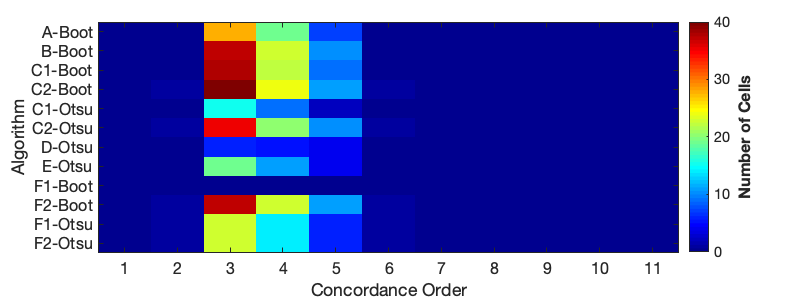

    
    % Supplementary
    fig12 = figure(12);
    clf
    set(fig12,'Position',[0, 200, 800, 300])
    imagesc(unique)
    %plot(unique')
    %surf(unique)
    %colormap(figureDetails.colorMap)
    colormap('jet')
    %xlim([0 7])
    %ylim([0 nAlgos+1])
    %plot(unique)
    % title('Uniquely Identified Time Cells', ...
    %     'FontSize', figureDetails.fontSize, ...
    %     'FontWeight', 'bold')
    xticklabels({'1', '2', '3', '4', '5', '6', '7', '8', '9', '10', '11'})
    %axis tight
    xlabel('Concordance Order', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    ylabel('Algorithm', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    yticks(1:size(unique, 1))
    yticklabels({'A-Boot', 'B-Boot', 'C1-Boot', 'C2-Boot', 'C1-Otsu', 'C2-Otsu', 'D-Otsu', 'E-Otsu', 'F1-Boot', 'F2-Boot', 'F1-Otsu', 'F2-Otsu'})
    z = colorbar;
    ylabel(z, 'Number of Cells', ...
        'FontSize', figureDetails.fontSize, ...
        'FontWeight', 'bold')
    set(gca, 'FontSize', figureDetails.fontSize)
    print(['/Users/ananth/Desktop/BoS/BoS-nI5/' num2str(dnum) '-sup' ...
        '_BoS_synthData' ...
        '_sup_' ...
        db.mouseName '_' num2str(db.date)], ...
        '-djpeg')

## End

toc

Elapsed time is 54.179275 seconds.
